# Oppgave 1

## a)

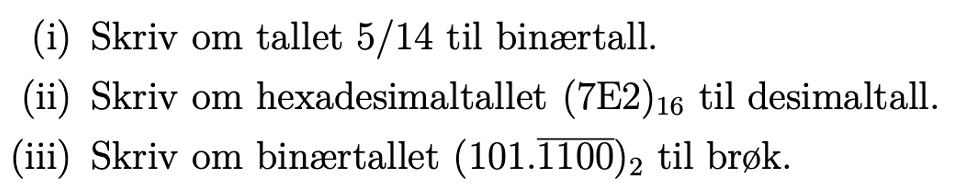

#### (i)


$$\begin{array}{l}
2*\frac{5}{14}=\frac{10}{14}+0\\
2*\frac{10}{14}=\frac{6}{14}+1\\
2*\frac{6}{14}=\frac{12}{14}+0\\
2*\frac{12}{14}=\frac{10}{14}+1
\end{array}$$


vi får $\frac{10}{14}\textrm{på}\;\textrm{nytt}\;\textrm{og}\;\textrm{får}\;\textrm{derfor}\;\textrm{at}\;{\frac{5}{14}}_{10} =0\ldotp {0\bar{101} }_2$

#### (ii)


$$7{\textrm{E2}}_{16} =\left(7*{16}^2 \right)+\left(14*{16}^1 \right)+\left(2*{16}^0 \right)=1792+224+2=2018$$


#### (iii)


$$101\ldotp {\bar{1100} }_2$$


heltallsdel: $101=4+1=5$

desimaldel: $\begin{array}{l}
\;\;\;\;x=\;\;\;\;\;\;\;\;0\ldotp 110011001100\ldotp \ldotp \ldotp \\
2^4 x=1100\ldotp 110011001100\ldotp \ldotp \ldotp 
\end{array}$      $15x={1100}_2 \Rightarrow 15x=12$


$$101\ldotp {\bar{1100} }_2 =5+\frac{12}{15}=\frac{87}{15}=\frac{29}{5}$$


## b)

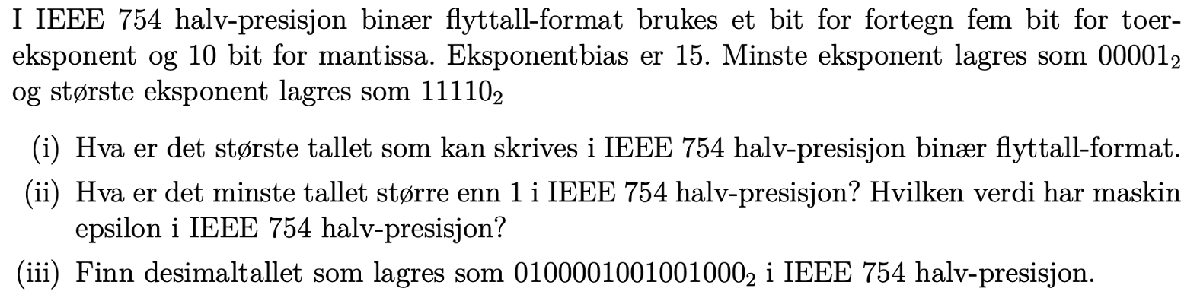

#### (i)


$${\left(-1\right)}^s *2^{e-15} *\left(1+\frac{m}{2^{10} }\right)$$


Største vi kan få er:


$${\left(-1\right)}^0 *2^{2^5 -1-15} *\left(1+\frac{2^{10} -1}{2^{10} }\right)$$


s = 0;
e = 30; % 11110_2 = 30_10
m = 2^10-1;
(-1)^s*2^(e-15)*(1+m/2^10)

ans =        65504


#### (ii)

minste over 1:

s = 0;
e = 15;
m = 1;
(-1)^s*2^(e-15)*(1+m/2^10)

ans =         1.001


e_mach = 1/2^10

e_mach =    0.00097656


#### (iii)


$$\begin{array}{l}
s=0\\
e={10000}_2 =16\\
m={1001001000}_2 =584
\end{array}$$


s = 0;
e = 16;
m = 584;
(-1)^s*2^(e-15)*(1+m/2^10)

ans =        3.1406


tilnærmet lik $\pi$

## c)


$$\frac{\sqrt{1+\varepsilon }-1}{1}=\frac{\left(\sqrt{1+\varepsilon }-1\right)\left(\sqrt{1+\varepsilon }+1\right)}{\sqrt{1+\varepsilon }+1}=\frac{{\left(\sqrt{1+\varepsilon }\right)}^2 -1}{\sqrt{1+\varepsilon }+1}=\frac{1+\varepsilon -1}{\sqrt{1+\varepsilon }+1}=\frac{\varepsilon }{2}$$


sqrt(1+e_mach)-1

ans =    0.00048816


e_mach/2

ans =    0.00048828


# Oppgave 2

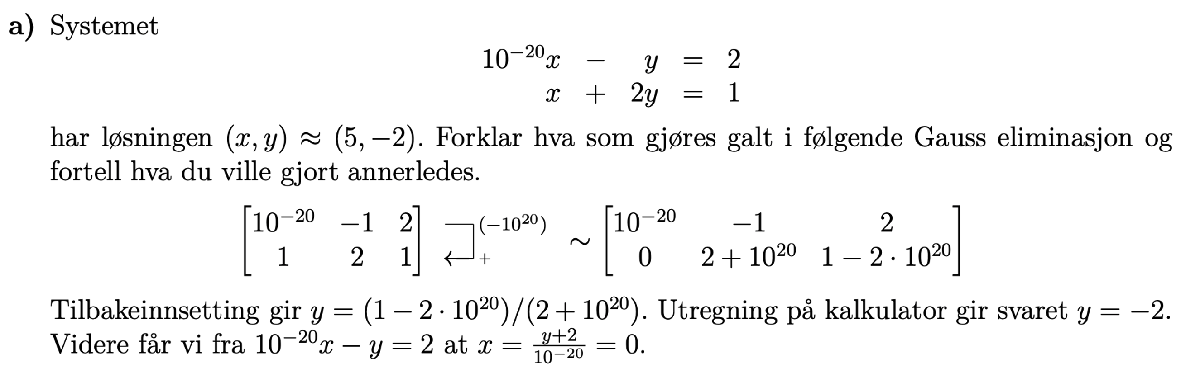

A = [10^-20 -1 2; 
	      1  2 1];
tilbakesubstitusjon(gausselim(A))

ans =      0
    -2


Probelemt her blir swamping: det betyr at når vi får $2+{10}^{20}$ og $1-2*{10}^{20}$ vil dette i praksis være ${10}^{20}$ siden denne verdien er så mye større enn de originale tallene

P = [0 1; 
	 1 0];
tilbakesubstitusjon(gausselim(P*A))

ans =      5
    -2


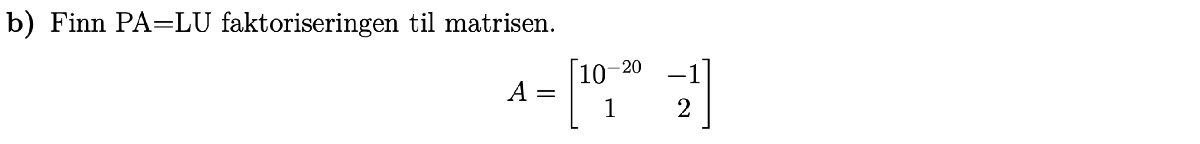

Gausseliminerer med pivotering:


$$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{10}^{-20}  & -1\\
1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2\\
{10}^{-20}  & -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 2\\
{10}^{-20}  & -1-{10}^{-20} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{cc}
1 & 2\\
{10}^{-20}  & -1
\end{array}\right\rbrack$$



$$P\;A=L\;U\;$$



$$\left\lbrack \begin{array}{cc}
0 & 1\\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{10}^{-20}  & -1\\
1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
{10}^{-20}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2\\
0 & -1
\end{array}\right\rbrack$$
